Type and execute the following commands in the command window and notice what happens

n=-4:4

n =     -4    -3    -2    -1     0     1     2     3     4


x=n.^2

x =     16     9     4     1     0     1     4     9    16


x>0

ans = 1×9 logical array
   1   1   1   1   0   1   1   1   1


x>=2

ans = 1×9 logical array
   1   1   1   0   0   0   1   1   1


x>1

ans = 1×9 logical array
   1   1   1   0   0   0   1   1   1


x>=15

ans = 1×9 logical array
   1   0   0   0   0   0   0   0   1


Opgave 2

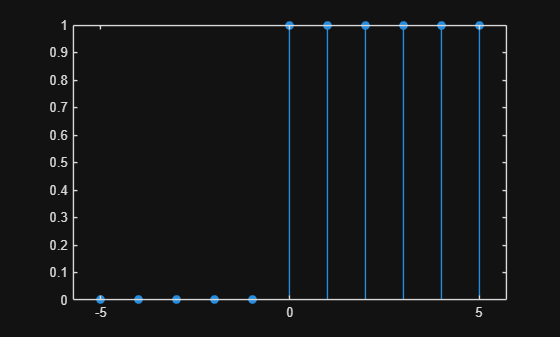

function [x,n] = unitimp(n0,n1,n2)
% Generates the unit impulse δ[n-n0]
% n0 = index where impulse is placed
% n1, n2 = range of n

n = n1:n2;
x = (n-n0) == 0;  % impulse at n0
end


function [x,n] = unitstep(n0,n1,n2)
% Generates the unit step u[n-n0]
% n0 = step index
% n1, n2 = range of n

n = n1:n2;
x = (n-n0) >= 0;  % 1 for n >= n0
stem(n,x,'filled');
end

unitstep(0,-5,5);

Excersize 2

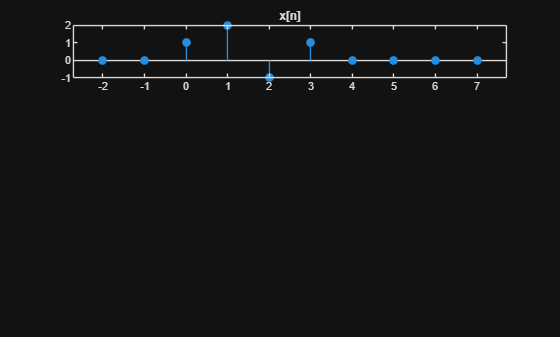

% Define x[n] exactly as in Fig. 2.7
n = -2:7;                 % index range for plotting
x = zeros(size(n));
x(n ==  0) = 1;
x(n ==  1) =  2;
x(n ==  2) =  -1;
x(n ==  3) =  1;


% Plots
figure;
subplot(4,1,1); stem(n,x,'filled'); title('x[n]');